clc;
clear;
syms t
syms theta1(t)  theta2(t) tau ddtheta1 ddtheta2
dtheta1 = diff(theta1, t);
dtheta2 = diff(theta2, t);


J1 = 0.0003716;
b1 = 3.611e-5;

J2 = 1.1431e-04;
J2_cm = 9.8995e-05;
b2 = 6.3306e-06;

g = 9.82;
L_mm = 0.0113445;
m2 = 0.119;
Lr = 0.085;

T_B_1 = [rotz(theta1), [0, 0, 0].'; [0, 0, 0, 1]];
T_1_2 = [rotx(-pi/2)*rotz(pi/2+theta2), [0, Lr, 0].'; [0, 0, 0, 1]];
T_B_2 = T_B_1*T_1_2;
p_B_2cm = T_B_2 * [L_mm, 0, -45.427*0.001, 1].';
v_2cm = diff(p_B_2cm, t);
v_2cm = v_2cm(t);
v_2cm_squared = v_2cm(1)^2+v_2cm(2)^2+v_2cm(3)^2;


E_kin1 = 1/2 *J1 * dtheta1^2;
E_kin2_rot = 1/2 *J2_cm * dtheta2^2;
E_kin2_tran = 1/2*m2*v_2cm_squared;
E_kin = E_kin1 + E_kin2_rot + E_kin2_tran;

E_pot = L_mm*g*m2*(1-cos(theta2));


L = E_kin - E_pot;
dLdx = simplify([diff(L, theta1(t)); diff(L, theta2(t))]);
dLddx = simplify([diff(L, dtheta1(t)); diff(L, dtheta2(t))]);
ddtdLddx = simplify(diff(dLddx, t));
Q = [tau; 0];

eq = simplify(ddtdLddx-dLdx) == Q;
eq_sub = subs(eq, [diff(theta1, t, 2), diff(theta2, t, 2)], [ddtheta1, ddtheta2]);

sol = solve(eq_sub, [ddtheta1, ddtheta2]);
ddtheta1_sol = simplify(sol.ddtheta1);
ddtheta2_sol = simplify(sol.ddtheta2);

%vpa(ddtheta1_sol, 3)
%vpa(ddtheta2_sol, 3)


% State vector and nonlinear state equation
x = [theta1(t); theta2(t); dtheta1(t); dtheta2(t)];
dx = [dtheta1(t); dtheta2(t); ddtheta1_sol; ddtheta2_sol];

% Input
u = tau;

% Operating point
x0 = [0; pi; 0; 0];
u0 = 0;

% Jacobians
A = jacobian(dx, x);
B = jacobian(dx, u);

% Evaluate at operating point
A_lin = simplify(subs(A, [x; u], [x0; u0]));
B_lin = simplify(subs(B, [x; u], [x0; u0]));

% Output matrix
C_lin = [0 1 0 0];
D_lin = 0;


A_num = double(A_lin)

A_num =          0         0    1.0000         0
         0         0         0    1.0000
         0   11.6245         0         0
         0  121.4064         0         0


B_num = double(B_lin)

B_num = 1.0e+03 *

         0
         0
    1.8762
    0.8769


C_num = double(C_lin)

C_num =      0     1     0     0


D_num = double(D_lin)

D_num = 0



sys = ss(A_num, B_num, C_num, D_num);

Trying now to find the transfer function for voltage to torque, since the above system is torque to theta2. For the derivation see 1.jpg and 2.jpg

(Instead of that we choose not to model the full dynamics of the dc motor since it should be faster and juts gives errors so instead we just chose it to be a first order transfer function

syms s
Km = 0.04704;
Kt = 0.04704;
Ra = 8.65;
La = 1.15*10^-3;
La = 0;
b = 3.611e-5;

VToTau = ((Km*Kt+(Ra+La*s)*(J1*s+b))/(Kt*(J1*s+b)))^-1;
[num, den] = numden(VToTau);
num_coeff = sym2poly(num);
den_coeff = sym2poly(den);
tau_V_tf = tf(num_coeff, den_coeff);

uhat = 1;
if uhat
    tau_V_tf = tf([Km/Ra], [1])
end


tau_V_tf =
 
  0.005438
 
Static gain.


Now we can calculate the system if the input is voltage and the output is theta2

% Controllability check
Co = ctrb(A_num, B_num);
disp('Controllability rank:')

Controllability rank:


disp(rank(Co))

     4




% full state output for LQR
C_lqr = eye(4);
D_lqr = zeros(4,1);

% LQR design (torque as input)
Q = diag([5, 10, 0.1, 0.1]);   % [theta1, theta2, dtheta1, dtheta2]
R = 1;
K_lqr = lqr(A_num, B_num, Q, R);

% Closed-loop with state feedback (torque input)
A_cl = A_num - B_num * K_lqr;
sys_cl = ss(A_cl, B_num, C_lqr, D_lqr);

% Account for motor gain (voltage input)
% Since uhat=1, tau_V_tf is just a scalar gain Km/Ra
motor_gain = Km/Ra;
K_lqr_voltage = K_lqr ./ motor_gain

K_lqr_voltage = 1.0e+03 *

   -0.4112    4.7022   -0.1374    0.4371


disp(K_lqr)

   -2.2361   25.5712   -0.7472    2.3768



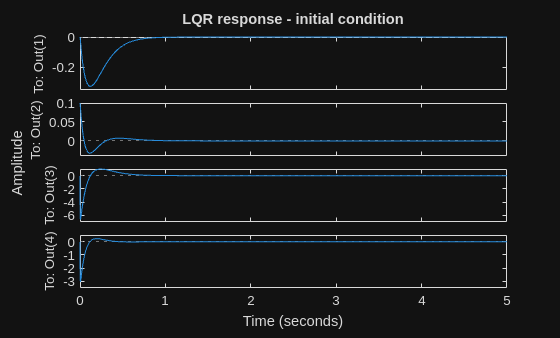

% Simulate from slightly perturbed upright position
% Remember: state-space is in deviations from operating point x0
x0_dev = [0; 0.1; 0; 0];   % 0.1 rad nudge on theta2
t_sim = 0:0.001:5;
initial(sys_cl, x0_dev, t_sim)
title('LQR response - initial condition')